# Basic ISETBio and Image Reconstruction Calculation

## Generate a retina with human optics and cone mosaic

% Load the display setup
% We assume the images are shown on a monitor

% This is a special display setup with high bit depth 
% to avoid quantization artifact
display = displayCreate('CRT12BitDisplay');

% Create a 1.0 deg foveal mosaic with a pupil size of 2.0 mm
% Note that to make the tutorial run faster, reduce the size of the mosaic
retina = ConeResponse('eccBasedConeDensity', true, 'eccBasedConeQuantal', true, ...
    'fovealDegree', 1.0, 'display', display, 'pupilSize', 2.0, 'integrationTime', 1.0);

Create cone moasic object: 
Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 225.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.666476, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 225.00 229.96 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustm

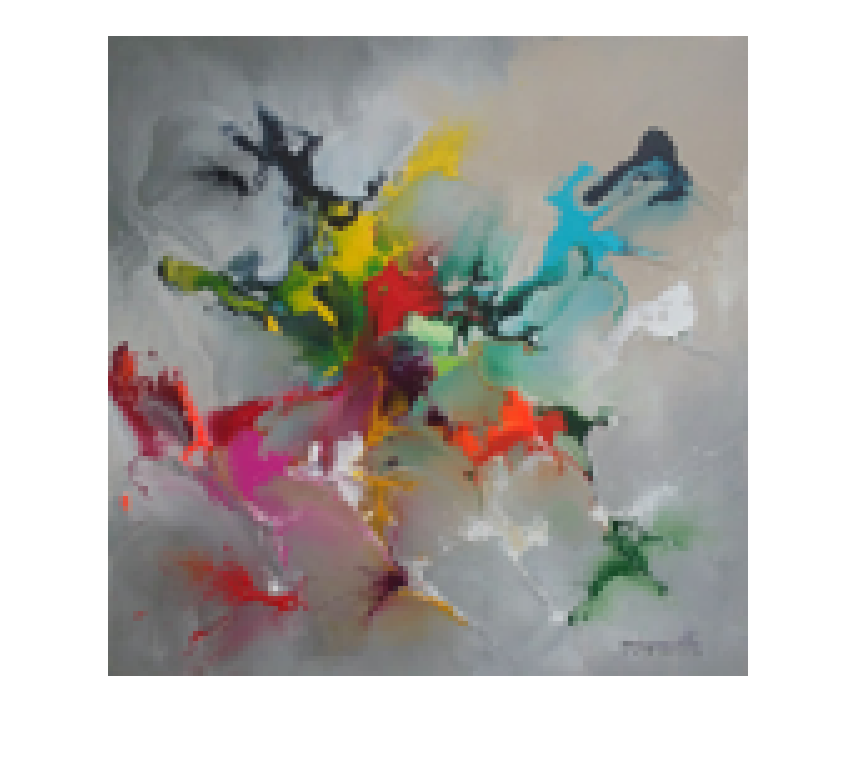

% Load an example image
% Note that to make the tutorial run faster, 
% reduce the size of the test image
imageSize = [128, 128, 3];
image = im2double(imread('images/9.jpeg'));
image = imresize(image, imageSize(1) / size(image, 1));

% Normalize to insure pixels are in the range of [0, 1]
image = (image - min(image(:)));
image = image ./ max(image(:));

assert(min(image(:)) >= 0);
assert(max(image(:)) <= 1);

figure();
imshow(image, 'InitialMagnification', 500);

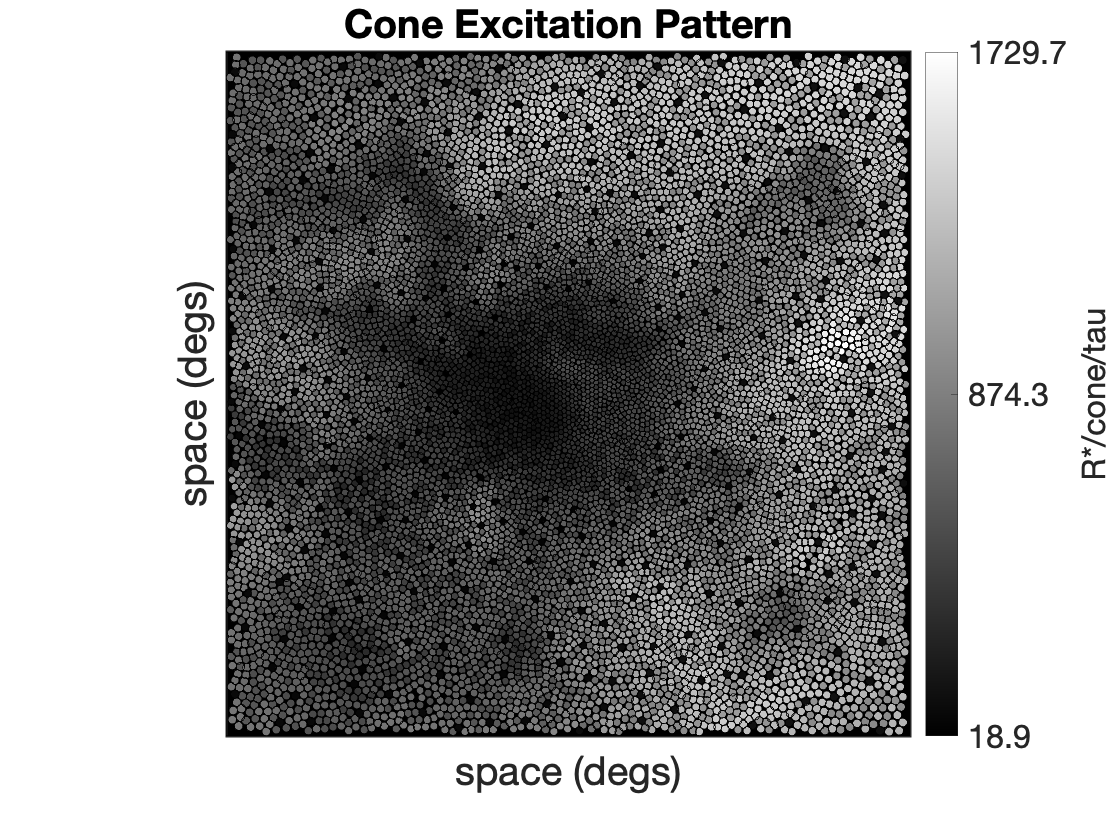

% Demo of compute cone responses:

% excitation is a 2D map of cone excitation
% allCone is a vector of cone excitation
% linearImage is the input image after display gamma function

% See ConeResponse class for detailed documentation
[excitation, ~, linearImage, allCone] = retina.compute(image);

% Show optical image (OI) and cone excitation
figure();
retina.visualizeExcitation();

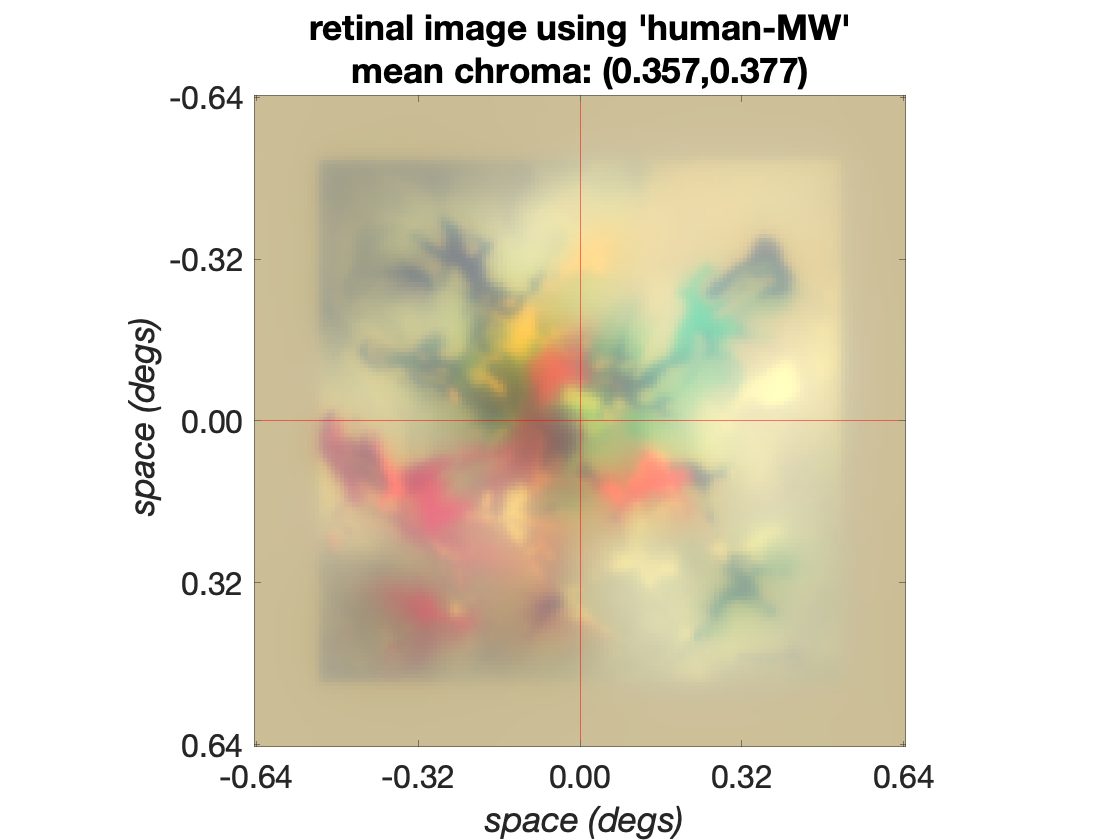

figure();
retina.visualizeOI();

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


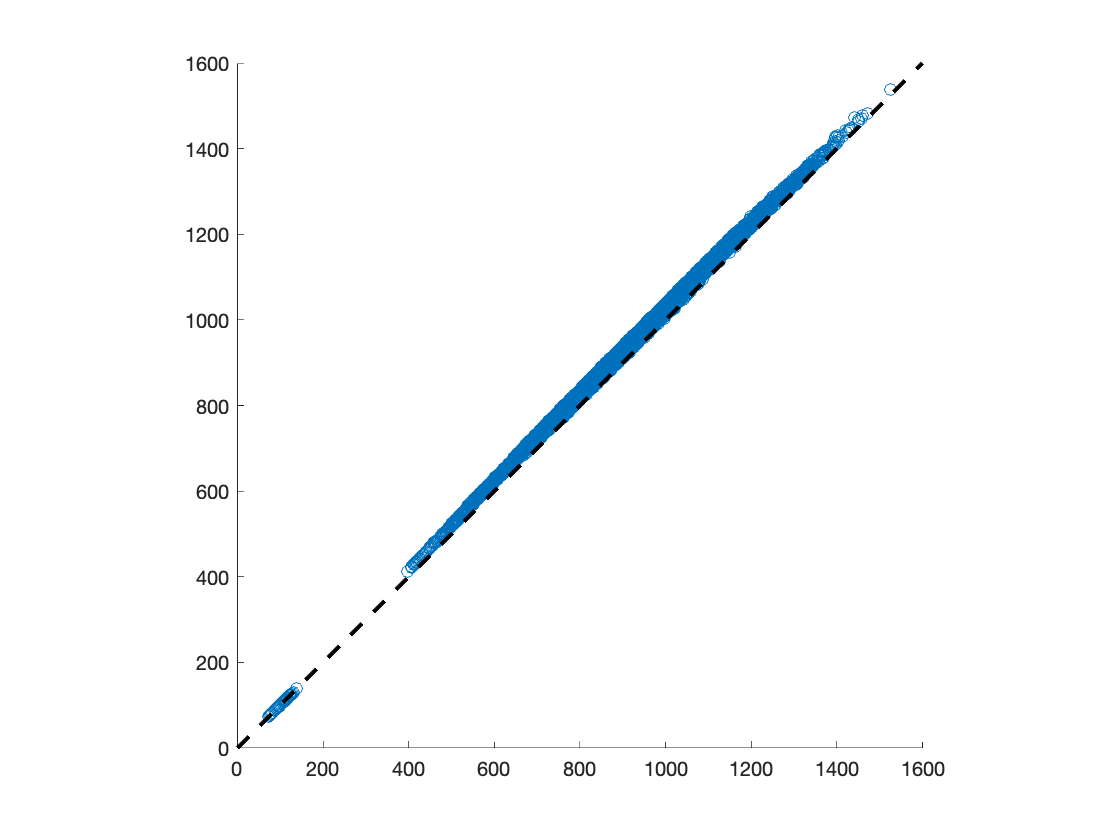

% Compute render matrix to represent the
% ISETBio calculation as a linear transformation
% the render matrix is used for likelihood computation
% in image reconstruction (see Methods)

% Note that this process is computation-intense
% reduce image size and retina mosaic size (deg)
% if you would like the process to be faster
render = retina.forwardRender(imageSize);

render = double(render);

## Image reconstruction from simulated cone responses

% Compute (noise-free) avearge cone response
response = render * linearImage(:);

% Cone response with added Poisson noise
response = poissrnd(response);

% Construct image estimator
prior = load('sparsePrior.mat');
regPara = 0.05; stride = 4; 

% Image estimator takes the render matrix (i.e., likelihood), the basis
% function for the image prior, the mean value of the image prior, the 
% "prior weight", stride parameter (see the Methods section of our paper)
estimator = PoissonSparseEstimator(render, inv(prior.regBasis), prior.mu', regPara, stride, imageSize);

% Estimate images
% Computation intense if large image size and cone mosaic is used
reconImage = estimator.runEstimate(response, 'maxIter', 1000, 'display', 'iter');

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.122882e+08    0.000e+00    5.329e+03
    1       2   -3.163358e+08    0.000e+00    4.900e+03    2.738e+01
    2       3   -3.163709e+08    0.000e+00    4.894e+03    2.379e-01
    3       4   -3.165587e+08    0.000e+00    4.858e+03    1.210e+00
    4       5   -3.167009e+08    0.000e+00    4.830e+03    8.875e-01
    5       6   -3.168881e+08    0.000e+00    4.790e+03    1.140e+00
    6       7   -3.170775e+08    0.000e+00    4.750e+03    1.136e+00
    7       8   -3.172838e+08    0.000e+00    4.698e+03    1.225e+00
    8       9   -3.175203e+08    0.000e+00    4.631e+03    1.404e+00
    9      10   -3.177961e+08    0.000e+00    4.551e+03    1.657e+00
   10      11   -3.178662e+08    0.000e+00    4.530e+03    4.242e-01
   11      12   -3.181509e+08    0.000e+00    4.438e+03    1.750e+00
   12      13   -3.184442e+08    0.000e+00    4

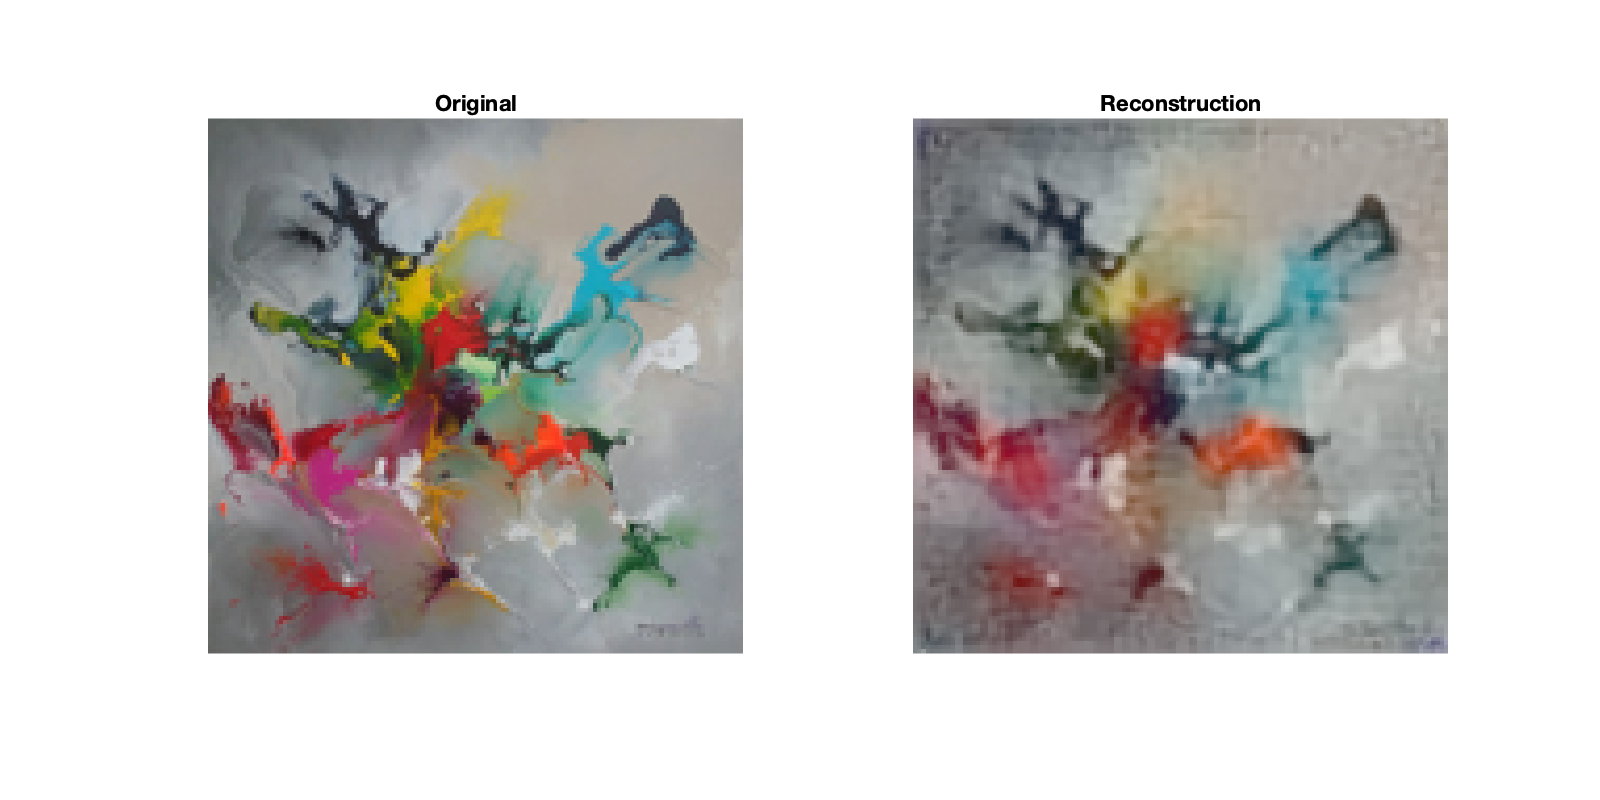

% Compare the original and reconstructed images
figure();
subplot(1, 2, 1);
imshow(image, 'InitialMagnification', 500);
title('Original')

% Reconstructed image is in linear pixel space
% Convert it back to RGB space
recon = gammaCorrection(reconImage, display);
subplot(1, 2, 2);
imshow(recon, 'InitialMagnification', 500);
title('Reconstruction')
set(gcf,'position',[0, 0, 800, 400]);